clear all;
close all;

Runge-Kutta 2nd order method

Delta_t=0.5;
t=0:Delta_t:10.0;
 
x(1)=1.0;
 
for n=1:length(t)-1
    k1=-x(n).^2;     
    k2=-(x(n)+Delta_t*k1).^2;     
    x(n+1)=x(n)+(Delta_t/2)*(k1+k2); 
end
 
plot(t,x,'ko-','linewidth',2,'Markersize',10)
hold on
 
tplot=0:0.01:10.0;
truesolution=@(t)(1./(t+1))

truesolution = function_handle with value:
    @(t)(1./(t+1))


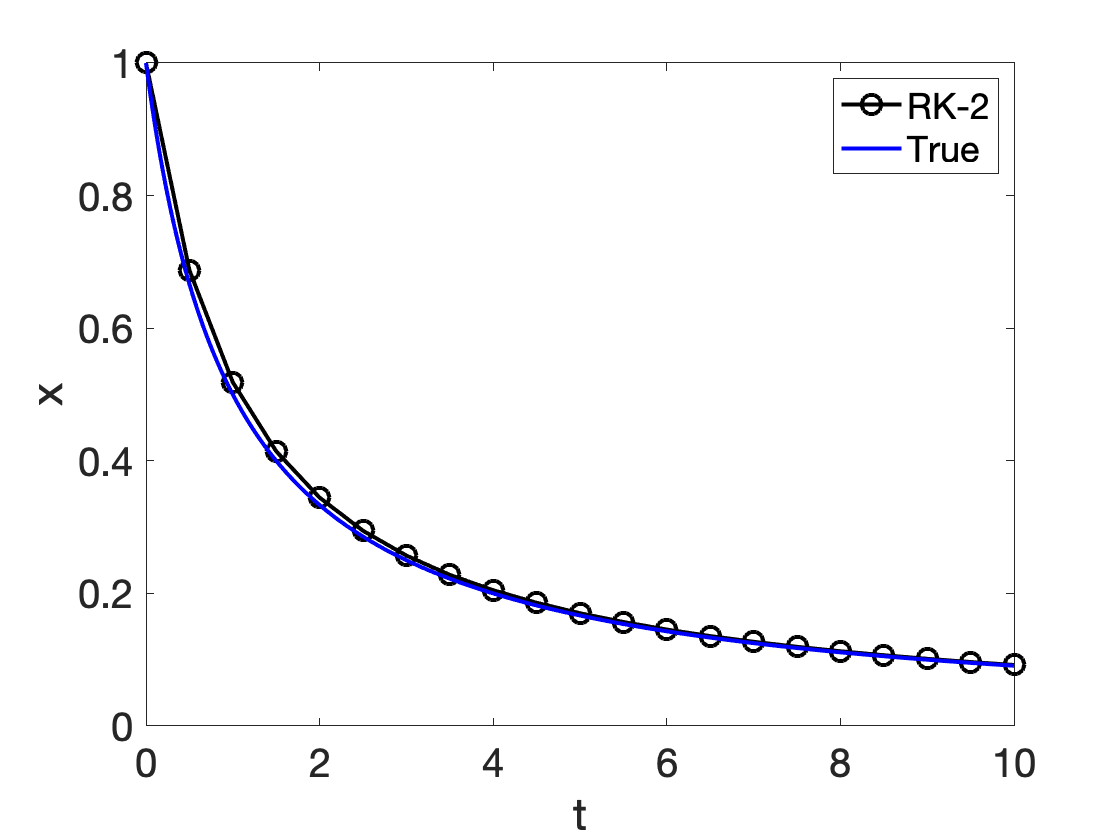

plot(tplot,truesolution(tplot),'b-','linewidth',2)
xlabel('t');
ylabel('x');
legend('RK-2','True');
axis([0 10 0 1])

Runge-Kutta 4th order method

t=0:Delta_t:10.0;
 
x(1)=1.0;
 
for n=1:length(t)-1
    k1=-x(n).^2;     
    k2=-(x(n)+(Delta_t/2)*k1).^2;  
    k3=-(x(n)+(Delta_t/2)*k2).^2;  
    k4=-(x(n)+Delta_t*k3).^2;  
    x(n+1)=x(n)+(Delta_t)*((1/6)*k1+(1/3)*(k2+k3)+(1/6)*k4); 
end
 
figure
plot(t,x,'ko-','linewidth',2,'Markersize',10)
hold on
 
tplot=0:0.01:10.0;
truesolution=@(t)(1./(t+1))

truesolution = function_handle with value:
    @(t)(1./(t+1))


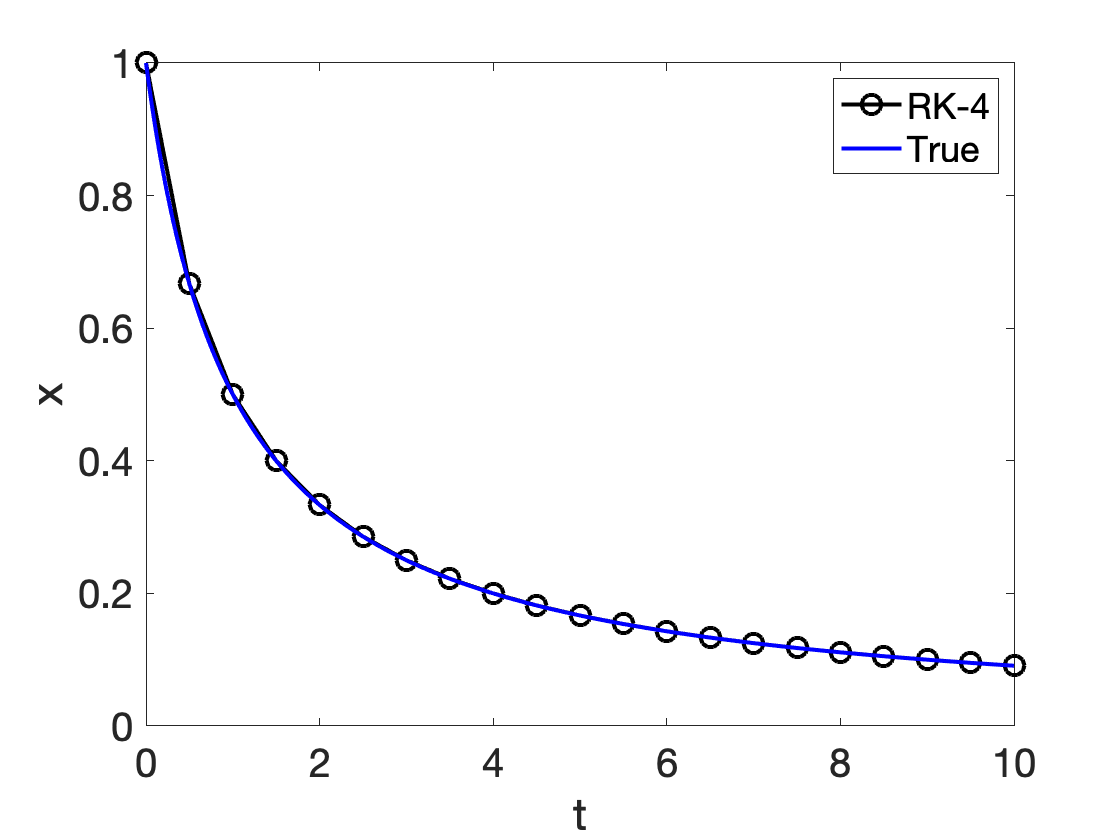

plot(tplot,truesolution(tplot),'b-','linewidth',2)
xlabel('t');
ylabel('x');
legend('RK-4','True');
axis([0 10 0 1])

Taylor's method order 2

t=0:Delta_t:10.0;
 
x(1)=1.0;
 
for n=1:length(t)-1
    x(n+1)=x(n)-Delta_t*(x(n).^2)+2*(Delta_t.^2/2)*(x(n).^3);
end

figure
plot(t,x,'ko-','linewidth',2,'Markersize',10)
hold on
 
tplot=0:0.01:10.0;
truesolution=@(t)(1./(t+1))

truesolution = function_handle with value:
    @(t)(1./(t+1))


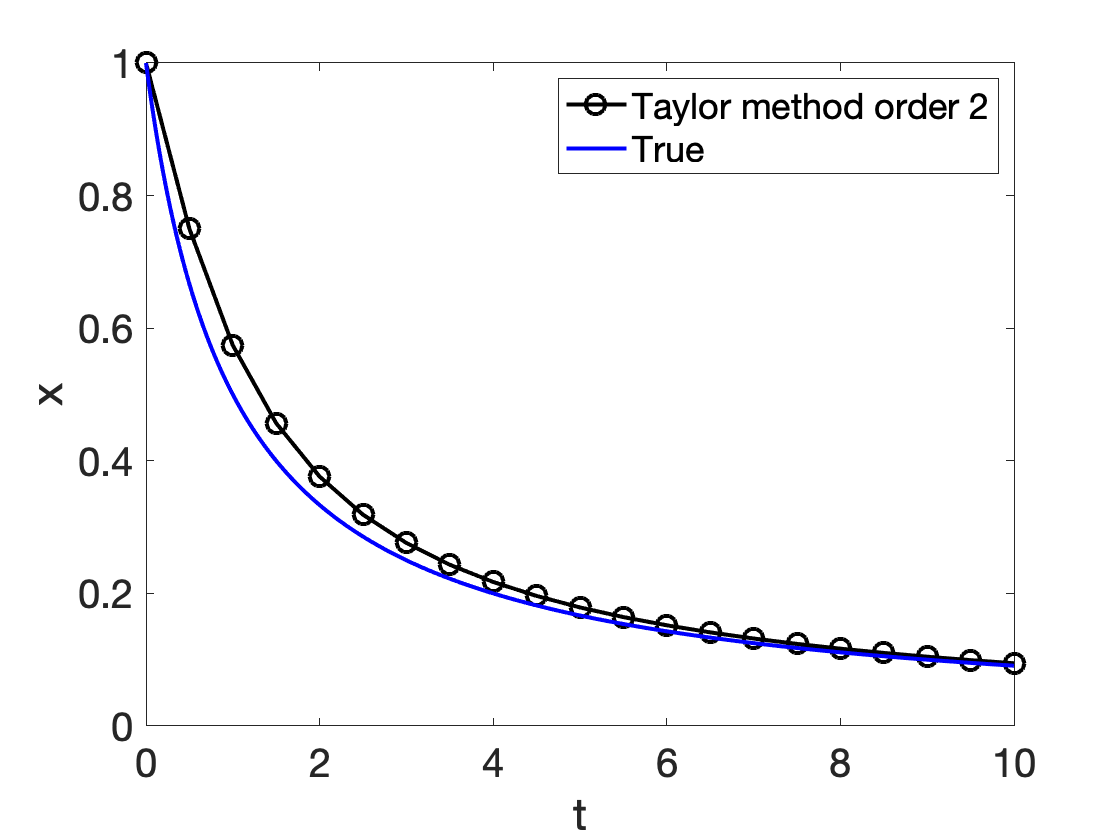

plot(tplot,truesolution(tplot),'b-','linewidth',2)
xlabel('t');
ylabel('x');
legend('Taylor method order 2','True');
axis([0 10 0 1])